load("lattice_calibration_data/15x15x15/trial4/lattice_data_1");
load("lattice_calibration_data/15x15x15/characteristic_2.mat");

fz_estimated = estimate_lattice_force(z,t_biased,t_inv,k,r(1),r(2),kr);

titlefsz = 20;
textfsz = 17;
axfsz = 15;
linewidth = 2;

figure;
% make the font visible for axis, legend, title, grid line size etc
% make the green darker
theme(figure,"light");
plot(t_biased,fz,"LineWidth",linewidth,"Color","red");

Unrecognized function or variable 'fz'.

hold on;
plot(t_biased,fz_estimated,"LineWidth",linewidth,"Color",[0 0.5 0]);
grid on;
ax = gca;
ax.FontSize = axfsz;
xlabel("Time(s)","FontSize",textfsz);
ylabel("Force(N)","FontSize",textfsz);
xlim([0,t_biased(end)]);
ylim([-10 4]);
legend(["Measured Force","Estimated Force"],"FontSize",textfsz);
title("Measured and Estimated Force vs time","FontSize",titlefsz);
saveas(gcf,"estimated_force.png")
hold off;

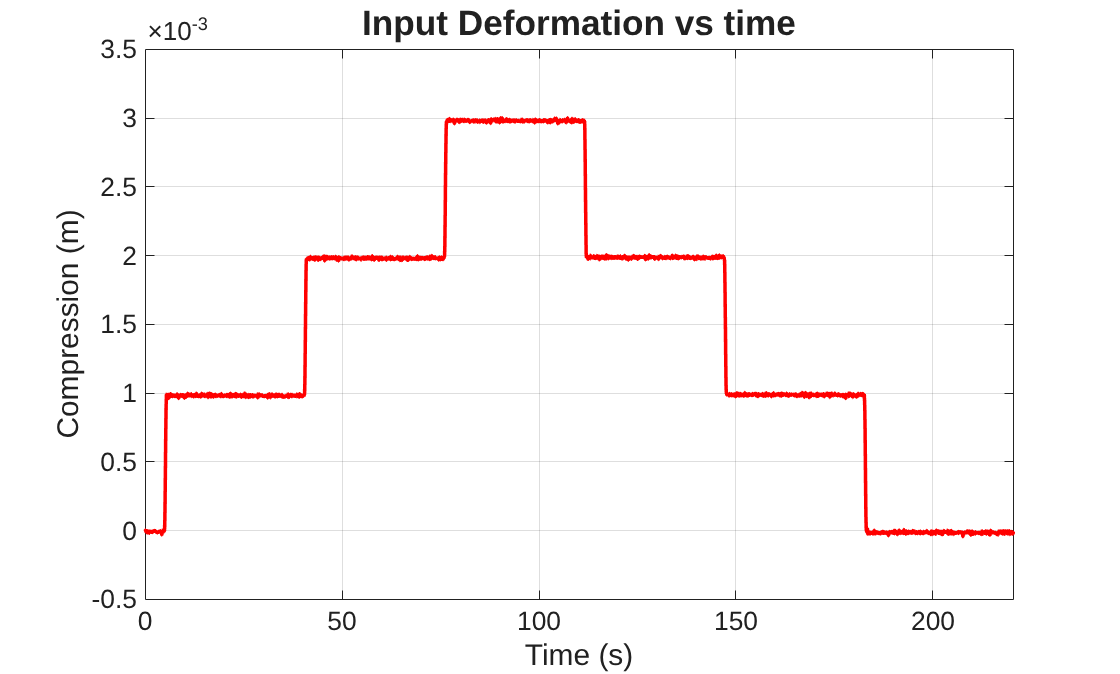

figure;
theme(figure,"light")
plot(t_biased,z,"LineWidth",linewidth,"Color","red");
xlim([0,t_biased(end)]);
hold on;
ax = gca;
ax.FontSize = axfsz;
title("Input Deformation vs time","FontSize",titlefsz);
xlabel("Time (s)","FontSize",textfsz);
ylabel("Compression (m)","FontSize",textfsz);

saveas(gcf,"input_deformation.png")

grid on;
hold off

% calculating the variance of the z positioning
std_deviation_z = std(z(4309:7507));
fprintf("Std deviation of z measurements: %s",num2str(std_deviation_z,3));

Std deviation of z measurements: 6.38e-06


std_deviation_fz = std(fz(18379:21979));
fprintf("Std deviation of fz measurements: %s",num2str(std_deviation_fz,3));

Std deviation of fz measurements: 0.00878


fz_estimate_residulas = abs(fz - fz_estimated);
mean_fz_error = mean(fz_estimate_residulas);
fprintf("Mean Fz estimation error : %s",num2str(mean_fz_error,3));

Mean Fz estimation error : 0.393


start_index = 4088 % movs till 4086, 50 data points or 0.5 s

start_index = 4088

window = [0.5;1;2;3;4]; % window sizes in seconds
freq = 100; %hz, sampling frequence

for i = 1: size(window,1)
    window_residuals = abs(fz(start_index:100*window(i) + start_index) - fz_estimated(start_index:100*window(i) + start_index)) - 0.4;
    mean_window_residual = mean(window_residuals);
    fprintf("Window : %s seconds, Mean Window Fz estimate residual: %s \n",num2str(window(i),3),num2str(mean_window_residual,3));
end 

Window : 0.5 seconds, Mean Window Fz estimate residual: 0.00681 
Window : 1 seconds, Mean Window Fz estimate residual: 0.0456 
Window : 2 seconds, Mean Window Fz estimate residual: 0.153 
Window : 3 seconds, Mean Window Fz estimate residual: 0.225 
Window : 4 seconds, Mean Window Fz estimate residual: 0.265 
